# Two-Tank System

This example shows how to identify a black-box dynamic model of a nonlinear two-tank system.

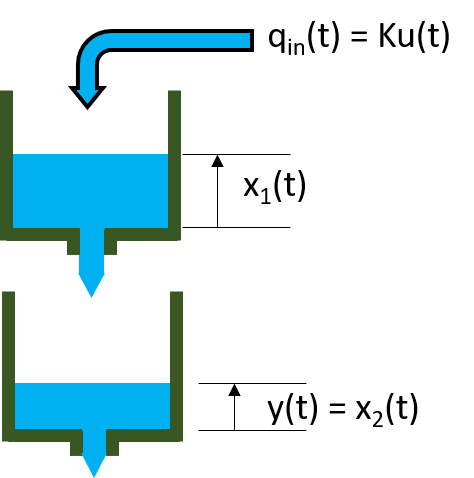

For this system, the input $u\left(t\right)$ is the voltage [V] applied to a pump, which generates an inflow to the upper tank. Water flows through a hole in the bottom of the upper tank and fills the lower tank. The output $y\left(t\right)$ of the two-tank system is the liquid level [m] of the lower tank.

The example uses measured data that contains 3000 input-output samples of a two-tank system generated using a sample time of 0.2 seconds. Load the data set and create an `iddata` object.

load twotankdata
z1f = iddata(y,u,0.2,'Name','Two-tank system');

This data set is also used in the following examples.

- [Two Tank System: C MEX-File Modeling of Time-Continuous SISO System](docid:ident_ug#example-ex09922248) — Nonlinear grey-box model estimation where physical equations describing the system are assumed

- [A Tutorial on Identification of Nonlinear ARX and Hammerstein-Wiener Models](docid:ident_ug#example-ex64198147) — Introductory example on black-box modeling using nonlinear ARX and Hammerstein-Wiener models.

This example is about Using Non-linear regressors to combined with ARX models NLARX

Plot the data and split into train and validation

## Preprocess Data

Before estimating a model, preprocess the data by first splitting it into estimation and validation data. Then, filter the data to remove high-frequency noise.

Split the data set into two subsets of equal size. You estimate the model using data set `z1` and validate the model using data set `z2`.

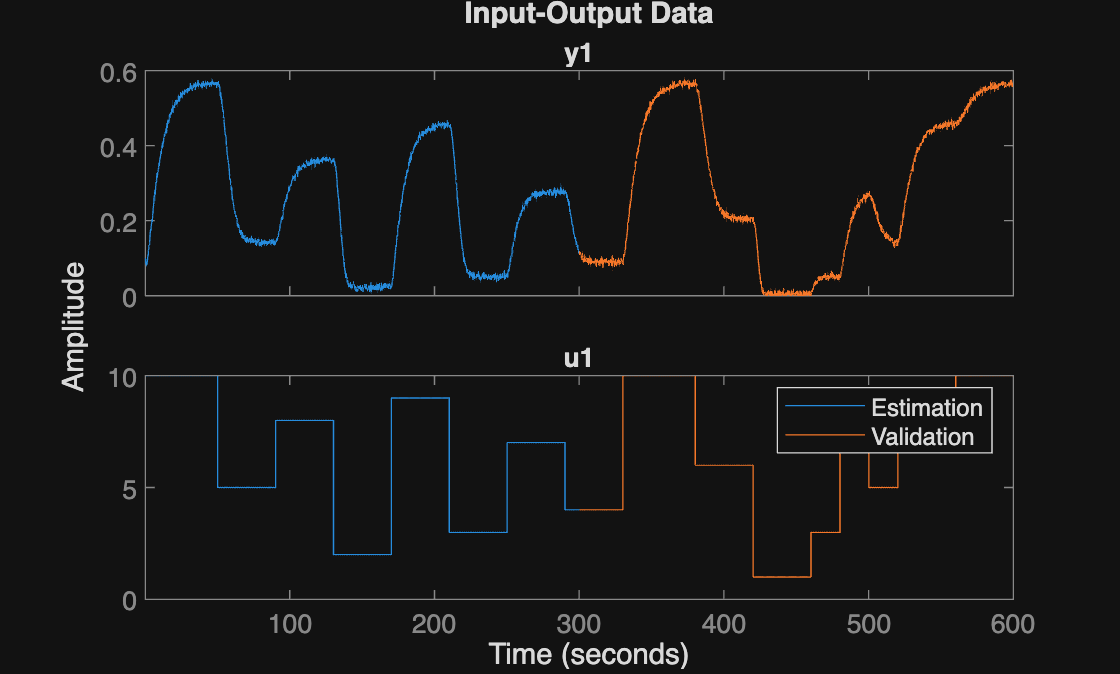

z1 = z1f(1:1500);
z2 = z1f(1501:3000);
plot(z1,z2)
legend('Estimation','Validation');

%%  Introduce non-linear regressors to better fit the data to the model, non-linear ARX model
% remove the offset from the data, and includ ethe offset as model
% parameter, offset makes the system non-linear.
% First non-linear model

% z1: training data
% z2: validation data

% copy the training data
data_est = z1;

names = [data_est.OutputName, data_est.InputName];

% Define the Linear Regressor vector
% L = [ y1(t-1), y1(t-2), u1(t), u1(t-1) u1(t-2) ]
L = linearRegressor(names,{1:2,0:2});

% model structure with offset (idLinear)
NL1 = nlarx(data_est, L, idLinear);

NL1.OutputFcn

ans = Linear Function
Inputs: y1(t-1), y1(t-2), u1(t), u1(t-1), u1(t-2)
Output: y1(t)

 Linear Function: initialized to [0.129 0.0203 -0.00911 -0.107 0.000451]
 Output Offset: initialized to -4.31e-17

    LinearFcn: 'Linear function parameters'
       Offset: 'Offset parameters'


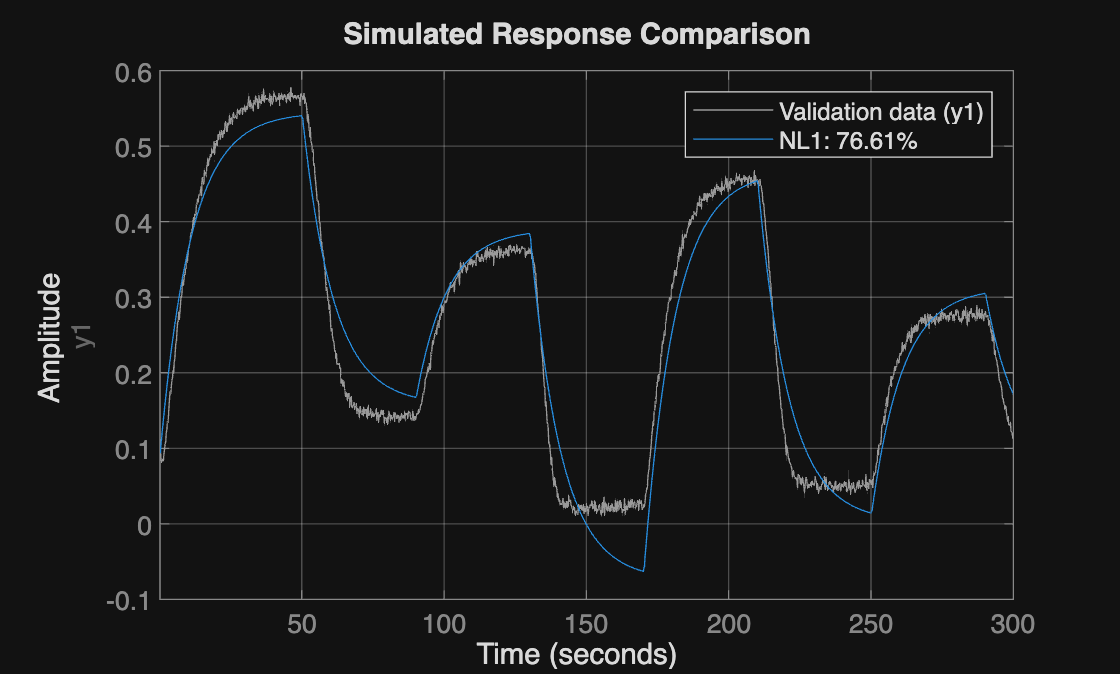


% Compare the model output to the data
figure; compare(data_est,NL1); grid on;

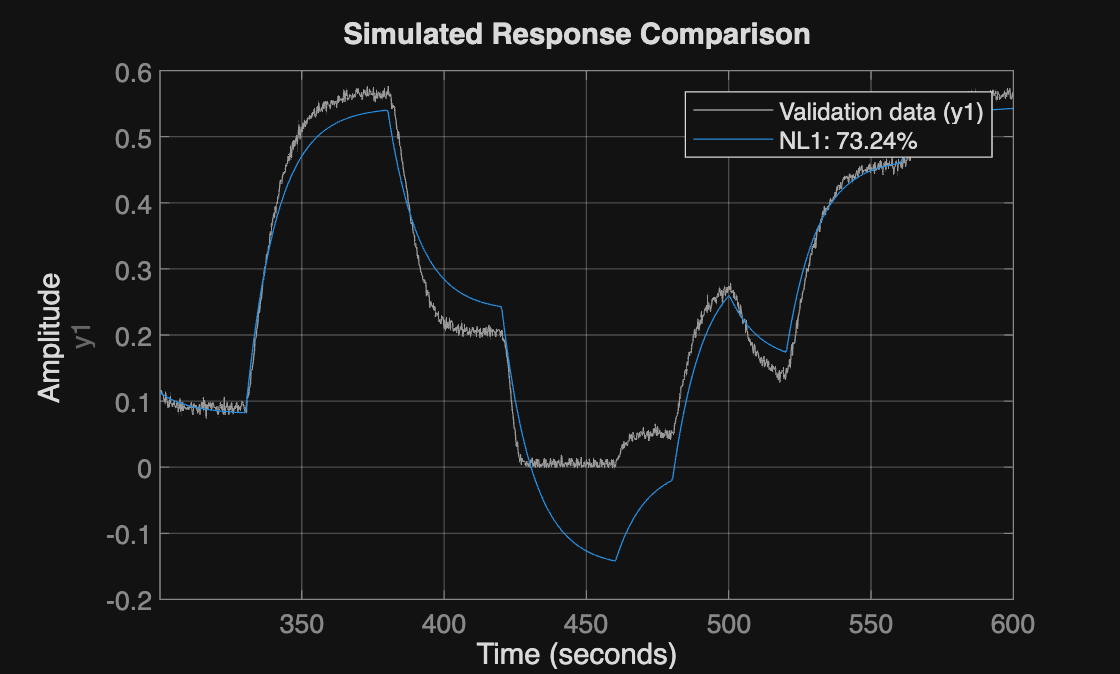

figure; compare(z2,NL1); grid on;

## Add non-linear regressors to the model

% include y(t-1)^2, u(t)^2, etc
% Build a custom regressor based on what we know about the problem
% Tank height at time t s a function of  the square root of the height at
% (t-1), y(t) is a function of sqrt(y(t-1)).
C = customRegressor({'y1'},{1},@(y)sqrt(y));

% Append this regressor C to the set of lienar regressors L
R = [L;C];

% Fit the new model to the data
NL2 = nlarx(data_est, R, idLinear);

NL2.OutputFcn

ans = Linear Function
Inputs: y1(t-1), y1(t-2), u1(t), u1(t-1), u1(t-2), sqrt(y1(t-1))
Output: y1(t)

 Linear Function: initialized to [0.129 0.0235 -0.0399 -0.0982 0.0125 -0.0005]
 Output Offset: initialized to -5.66e-17

    LinearFcn: 'Linear function parameters'
       Offset: 'Offset parameters'


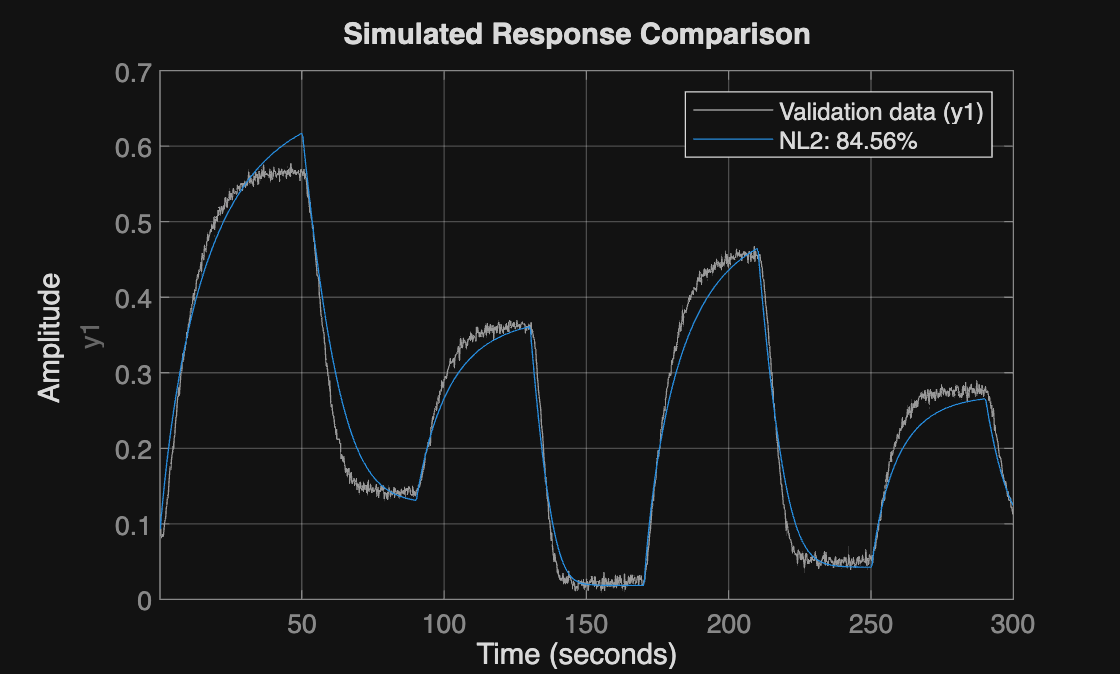


% Compare the model output to the data
figure; compare(data_est,NL1, NL2); grid on;

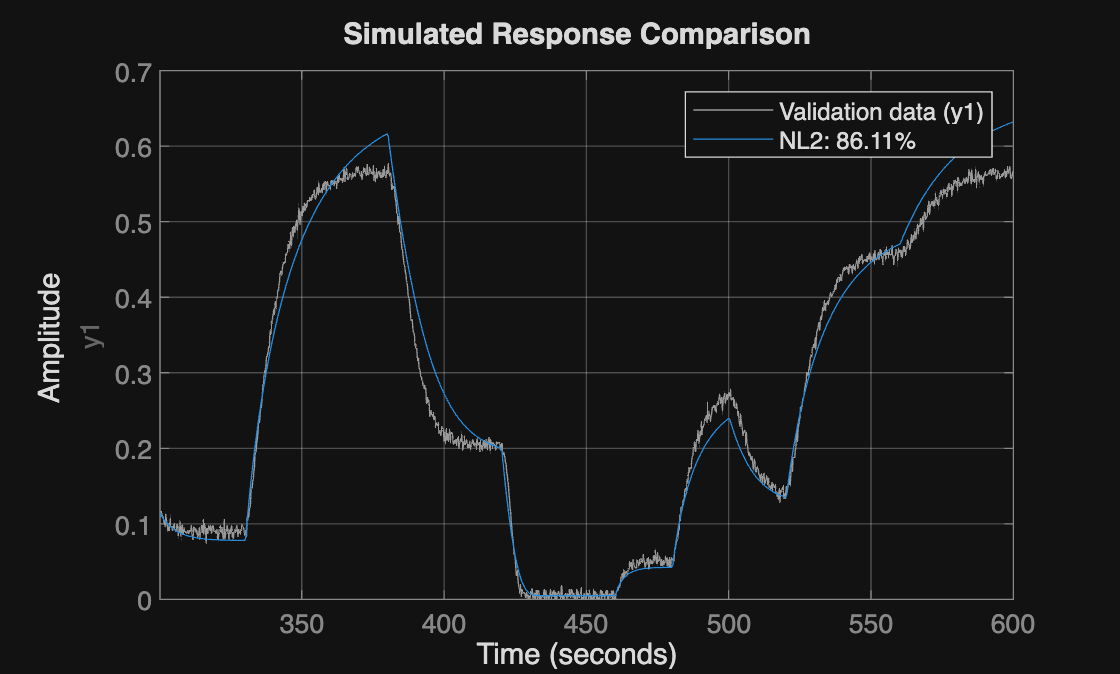

figure; compare(z2,NL1, NL2); grid on;